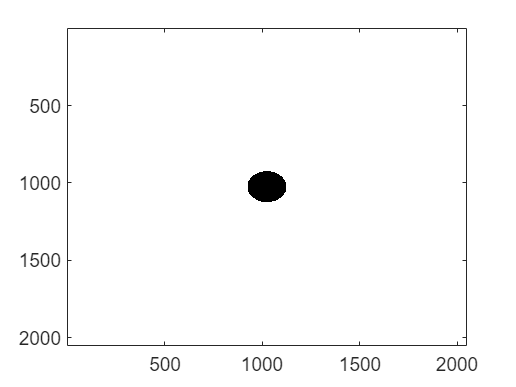

% Unidades
nm = 1E-9;
um = 1E-6;
mm = 1E-3;

M = 1;

% Tamaño de la representación
Nx = 2048;
Ny = Nx;

% Condiciones de muestreo
dx = 6.513*mm/(Nx*M); 
dy = dx;

% Longitud de Onda de iluminación
lambda = 650*nm;

% Apertura númerica
AN = 0.25;

%La imagen pasará por un primer lente, el cual es un 
% objetivo 10x, en su distancia focal, lo cual representa 
% una transformada de Fourier.

f2 = 200*mm;
M = 1; 

%Leer imagenes 

% Imagen1 = imread('SiemensStar_2048_AD.png');
% Imagen2 = imread('SiemensStar_2048_AD.png');
% Imagen3 = imread('SiemensStar_2048_AD.png');

Imagen1 = filtroCircular([Nx/2 Ny/2], 100, [Nx Ny]);
Imagen2 = filtroCircular([(Nx/2)-100 Ny/2], 200, [Nx Ny]);
Imagen3 = filtroCircular([(Nx/2)+100 Ny/2], 300, [Nx Ny]);

Imagen1 = im2gray(im2double(Imagen1));
Imagen1 = ~Imagen1;
Imagen2 = im2gray(im2double(Imagen2));
Imagen2 = ~Imagen2;
Imagen3 = im2gray(im2double(Imagen3));
Imagen3 = ~Imagen3;


imagesc(Imagen1)
colormap("gray")

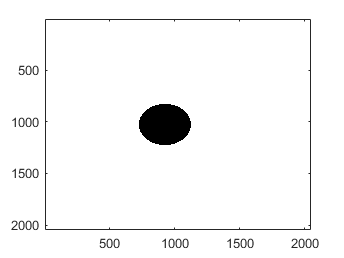

imagesc(Imagen2)
colormap("gray")

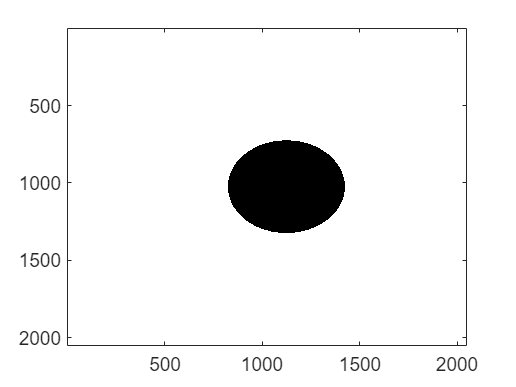

imagesc(Imagen3)
colormap("gray")


%Proceso para un microscopio de un foton. 

%Se usara un indicador para elegir el plano focal, si el
%que contiene a la imagen 1, 2 o 3. 

indicador = 1; 

% if indicador == 1
    %La imagen uno se encontrara en foco, por lo que no deberá hacerse
    %propagación inicial. 
    [salidafocal, observacion, pupila] = microscopio(Imagen1,M,f2,AN,Nx,Ny,dx,dy,lambda);

df_0 = 1.9960e-05

rpupila = 0.0500

rpupilaf = 489.2578

    cadena = "primera imagen microscopio"

cadena = "primera imagen microscopio"

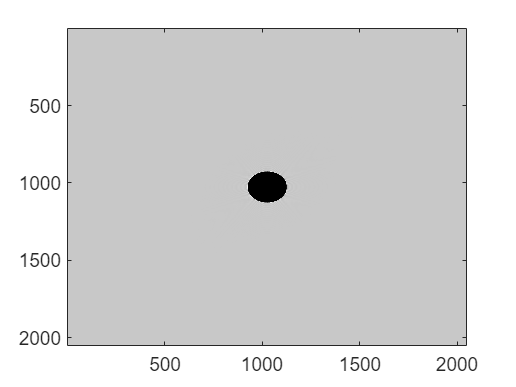

    salidafocalmod = (abs(salidafocal)).^2;
    imagesc(salidafocalmod)

    %La imagen dos se encontrara fuera de foco por 10 mm, por lo que
    %primero se debe propagar hasta el plano focal. En este caso usaremos
    %(Definir que propagación usar). 

    distIm2 = 20*mm;
    
    Imagen2Prop = transformadaFresnel(Imagen2, dx,dy,Nx,Ny,distIm2,lambda, zoom=false);
 
    %La imagen tres se encontrara fuera de foco por 20mm, por lo que primero
    %se debe propagar hasta el plano focal. 

    
    cadena1 = "figura2"

cadena1 = "figura2"

    Imagen2Propmod = (abs(Imagen2Prop)).^2;
    [salida2, observacion2, pupila2] = microscopio(Imagen2Prop, M, f2, AN, Nx, Ny, dx, dy, lambda);

df_0 = 1.9960e-05

rpupila = 0.0500

rpupilaf = 489.2578

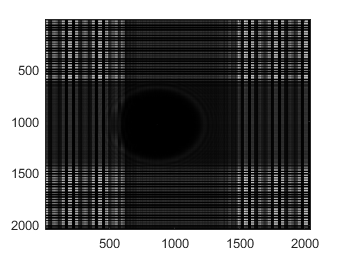

    salida2mod = (abs(salida2)).^2;
    imagesc(Imagen2Propmod)

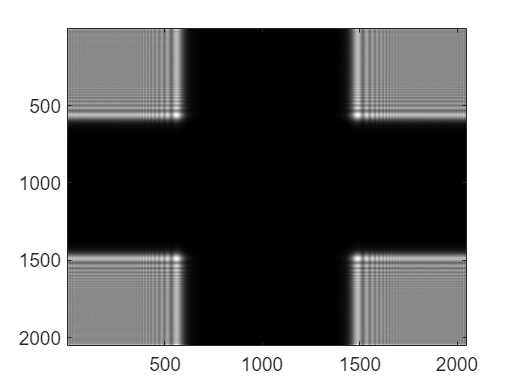

    imagesc(salida2mod)


    distIm3 = 40*mm;

    Imagen3Prop = transformadaFresnel(Imagen3, dx,dy,Nx,Ny,distIm3,lambda, zoom = false);
    
    
    cadena2 = "figura3"

cadena2 = "figura3"

    Imagen3Propmod = (abs(Imagen3Prop)).^2;
    [salida3, observacion3, pupila3] = microscopio(Imagen3Prop, M, f2, AN, Nx, Ny, dx, dy, lambda);

df_0 = 1.9960e-05

rpupila = 0.0500

rpupilaf = 489.2578

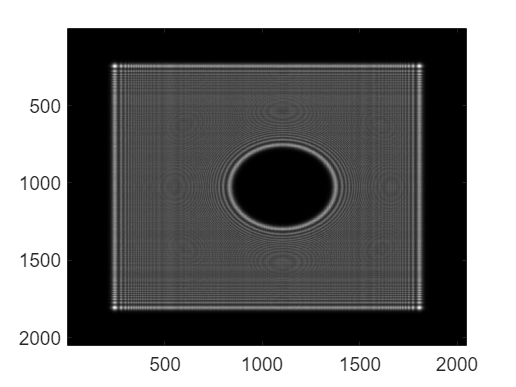

    salida3mod = (abs(salida3)).^2;
    imagesc(Imagen3Propmod)

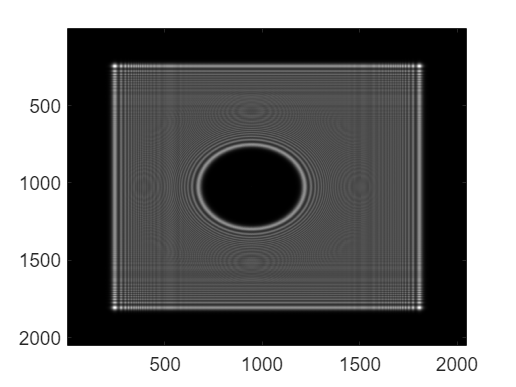

    imagesc(salida3mod)

    
    colormap("gray")

    
% elseif indicador == 2
%     [salidafocal, observacion, pupila] = microscopio(Imagen2,M,f2,AN,Nx,Ny,dx,dy,lambda)
% else
%     [salidafocal, observacion, pupila] = microscopio(Imagen3,M,f2,AN,Nx,Ny,dx,dy,lambda)
% end

superposicionFinal = salidafocal+salida2+salida3;
superposicionFinal = ((abs(superposicionFinal)).^2);
imagesc(superposicionFinal)